# **Generation of a biquadratic quadrilateral mesh**

It returnd a biquadratic quadrilateral mesh based on a provided bilinear quadrilateral mesh:

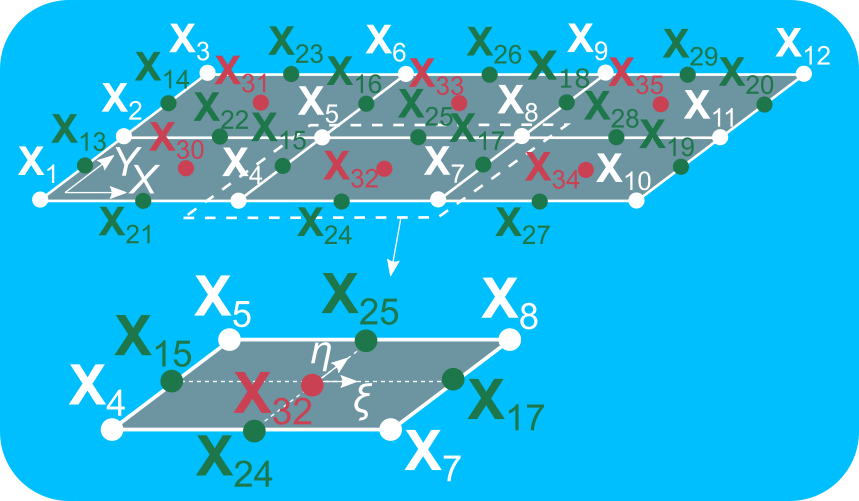

function [mshQ2, biasX] = generateBiquadraticQuadrilateralMesh ...
    (numElx, numEly, nodesX, nodesY, mshQ1, numNodesElQ1, numNodesElQ2)

## **Function Description**

It returns a mesh corresponding to biquadratic quadrilateral elements.

**                   Input :**

  `numElx`, `numEly` : Number of elements along the $X$- and the $Y$-directions

  `nodesX`, `nodesY` : $X$- and $Y$-Cartesian coordinates of the nodes in the mesh

        `numNodesEl` : Number of nodes per bilinear quadrilateral element

                  `mshQ1` : Structure containing the nodes and elements of the bilinear quadrilateral mesh onto which the biquadratic bilinear mesh is created

                                 .nodes : Array containing the Cartesian coordinates of the nodes in the mesh

                            .elements : Array containing the node IDs per element in the mesh

`  numNodesElQ1` : Number of nodes per bilinear quadrilateral element

`  numNodesElQ2` : Number of nodes per biquadratic quadrilateral element

**               Output :**

                 `mshQ2` : Structure containing the nodes and elements of the biquadratic quadrilateral mesh

                                .`nodes` : Array containing the Cartesian coordinates of the nodes in the mesh

                           .`elements` : Array containing the node IDs per element in the mesh

                 `biasX` : Number of nodes of the background bilinear quadrilateral mesh and the set of intermediate for each edge along the y-direction

## **Function Implementation**

### **Input validation**

arguments
    numElx (1, 1) double {mustBeInteger, mustBePositive}
    numEly (1, 1) double {mustBeInteger, mustBePositive}
    nodesX (:, :) double
    nodesY (:, 1) double {mustHaveEqualNumberOfElements(nodesY, nodesX)}
    mshQ1 (1, 1) {mustHaveNodesAndElements}
    numNodesElQ1 (1, 1) double {mustBeInteger, mustBePositive}
    numNodesElQ2 (1, 1) double {mustBeInteger, mustBePositive}
end

### Intermediate boundary nodes along the *Y*-direction

nodesY_reshaped = reshape(nodesY, numEly + 1, numElx + 1);
nodes_Q2_Y_x = zeros(numEly, numElx + 1, "like", nodesX);
nodes_Q2_Y_y = zeros(numEly, numElx + 1, "like", nodesX);
for ii = 1:numEly
    for jj = 1:numElx + 1
        nodes_Q2_Y_x(ii, jj) = mean(nodesX(ii:ii + 1, jj));
        nodes_Q2_Y_y(ii, jj) = mean(nodesY_reshaped(ii:ii + 1, jj));
    end
end

#### Adding the nodal coordinates to `mesh.nodes`

bias_Y = numel(mshQ1.nodes(:, 1));
mshQ2.nodes = [mshQ1.nodes; [nodes_Q2_Y_x(:) nodes_Q2_Y_y(:) zeros(numEly*(numElx + 1), 1)]];

#### Adding the element connectivity to `mesh.elements`

mshQ2.elements = zeros(length(mshQ1.elements(:, 1)), numNodesElQ2);
mshQ2.elements(:, 1:numNodesElQ1) = mshQ1.elements;
counterEl = 1;
for ii = 1:numElx
    adv = (ii - 1)*numEly + bias_Y;
    advplus1 = ii*numEly + bias_Y;
    for jj = 1:numEly
        mshQ2.elements(counterEl, numNodesElQ1 + 1:numNodesElQ1 + 2) = [jj+adv jj+advplus1];
        counterEl = counterEl + 1;
    end
end

### Intermediate boundary nodes along the *X*-direction

nodes_Q2_X_x = zeros(numEly + 1, numElx, "like", nodesX);
nodes_Q2_X_y = zeros(numEly + 1, numElx, "like", nodesX);
for ii = 1:numEly + 1
    for jj = 1:numElx
        nodes_Q2_X_x(ii, jj) = mean(nodesX(ii, jj:jj + 1));
        nodes_Q2_X_y(ii, jj) = mean(nodesY_reshaped(ii, jj:jj + 1));
    end
end

#### Adding the nodal coordinates to `mesh.nodes`

biasX = numel(mshQ2.nodes(:, 1));
mshQ2.nodes = [mshQ2.nodes; [nodes_Q2_X_x(:) nodes_Q2_X_y(:) zeros((numEly + 1)*numElx, 1)]];

#### Adding the element connectivity to `mesh.elements`

counterEl = 1;
for ii = 1:numElx
    for jj = 1:numEly
        adv = (ii - 1)*(numEly + 1) + jj + biasX;
        mshQ2.elements(counterEl, numNodesElQ1 + 3:numNodesElQ1 + 4) = [adv adv+1];
        counterEl = counterEl + 1;
    end
end

### Middle nodes

bias = numel(mshQ2.nodes(:, 1));
for ii = 1:numel(mshQ1.elements(:, 1))
    barycenter =  mean(mshQ2.nodes(mshQ2.elements(ii, 1:4),:), 1);
    mshQ2.nodes = [mshQ2.nodes; barycenter];
    mshQ2.elements(ii, end) = ii + bias;
end

end